# [Draw Classification](https://apmonitor.com/pds/index.php/Main/DrawClassification)

**Objective**: The dataset "drawdata.txt" consists of a sereis of coordinates labeled either "a","b","c" or "d". Read in this this dataset and run existing code with it as an introduction to supervised learning methods. For this section, the classification methods that will be reviewed will be:

- Support Vector

- K-nearest neighbor 

- Decision tree

- Discriminant

- Naive Bayes

- Neural Network

- Random Forest

- Adaboost  

## Data Preperation

url = 'http://apmonitor.com/pds/uploads/Main/drawdata.txt';
data = readtable(url);

head(data);

      x         y         z  
    ______    ______    _____

     234.1    428.36    {'a'}
    213.01    432.22    {'a'}
    165.34    378.98    {'a'}
    180.38    395.18    {'a'}
    188.17    366.71    {'a'}
    142.82    379.96    {'a'}
    217.18    417.27    {'a'}
    198.67    423.96    {'a'}



### **Describe Data**

A statistical overview of the data reveals the number and distribution of points.

summary(data);

Variables:

    x: 1562×1 double

        Values:

            Min        42.604 
            Median     302.96 
            Max        669.09 

    y: 1562×1 double

        Values:

            Min        119.53 
            Median     304.97 
            Max        496.44 

    z: 1562×1 cell array of character vectors



### **Visualize Data**

Create plots to view data distribution. A classifier creates boundaries to define regions for 2 or more labels. [Data visualization](https://www.mathworks.com/discovery/data-visualization.html) can give insights on how to build an effective classifier and [identify any data quality issues ](https://www.mathworks.com/discovery/data-cleaning.html)such as outliers.

% Create the pairplot using the 'gplotmatrix' function
figure;
xnames = {'x','y'}

xnames = 1×2 cell array
    {'x'}    {'y'}


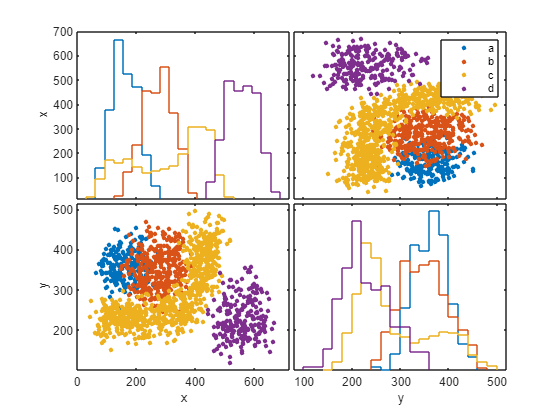

gplotmatrix([data.x data.y],[],data.z,[],[],10,[],[],xnames)

### **Encode Data**

[Ordinal number encoding](https://www.mathworks.com/help/deeplearning/ref/onehotencode.html) translates text labels (`a`, `b`, `c`, `d`) into numeric labels (`0`, `1`, `2`, `3`). One-hot encoding and feature hashing are two alternative encoding methods.

[~, data.z] = ismember(data.z, unique(data.z));

### **Scale Data**

Many classification methods work best with [scaled data](https://www.mathworks.com/help/matlab/ref/double.normalize.html). Only the features `x` and `y` are scaled while the label `z` is not scaled to preserve the integer values.

data.('xs') = normalize(data).x;
data.('ys') = normalize(data).y;
head(data);

      x         y       z       xs         ys   
    ______    ______    _    ________    _______

     234.1    428.36    1    -0.57998     1.6095
    213.01    432.22    1    -0.72398     1.6598
    165.34    378.98    1     -1.0495    0.96632
    180.38    395.18    1    -0.94681     1.1774
    188.17    366.71    1    -0.89362    0.80651
    142.82    379.96    1     -1.2033     0.9792
    217.18    417.27    1     -0.6955     1.4651
    198.67    423.96    1    -0.82188     1.5522



### **Split Data**

[Split data](https://www.mathworks.com/help/deeplearning/ref/dividerand.html) into train (80%) and test (20%) sets. The test set is to validate the fit created from the training data. You can also split data with the [classification learner app](https://www.mathworks.com/help/stats/select-data-and-validation-for-classification-problem.html).

[trainidx,~,testidx] = dividerand(height(data),0.8,0,0.2);
train = data(trainidx,:);
test = data(testidx,:);

## Supervised Learning Classifier

For more information on the different classifier methods, go to this [link](https://www.mathworks.com/discovery/supervised-learning.html).

For each classifier we'll show a confusion matrix result. A confusion matrix shows true positive, false positive, true negative, and false negative groups from the test set. Generate a confusion matrix for each classifier and compare the different models.

### **Support Vector**

Here are conceptual details for [support vector clasisfiers](https://apmonitor.com/pds/index.php/Main/SupportVectorClassifier).

Three methods to train a support vector classifier in MATLAB include [suport vector machine classification](https://www.mathworks.com/help/stats/support-vector-machine-classification.html), [fitcecoc](https://www.mathworks.com/help/stats/fitcecoc.html), and [templatesvm](https://www.mathworks.com/help/stats/templatesvm.html).

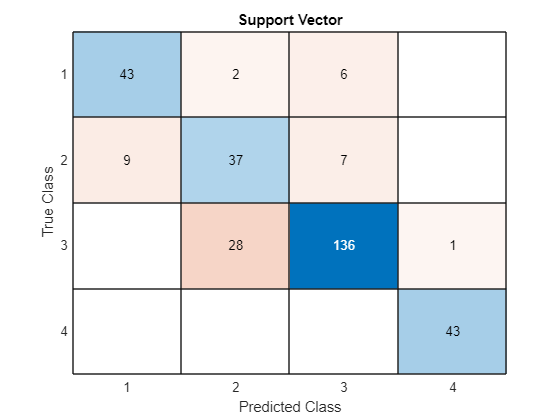

% Fit model
lr = fitcecoc(train,"z",'Learners','svm');

% Predict values
lf_y = predict(lr,test);

% Calculate the Accuracy
C = confusionmat(lf_y,test.z);
confusionchart(C);
title('Support Vector');

accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.83


### **KNN**

Here are conceptual details for [K-nearest neighbors](https://apmonitor.com/pds/index.php/Main/KNearestNeighbors).

Two ways to train a K-nearest neighbors in MATLAB include [classification KNN](https://www.mathworks.com/help/stats/classificationknn.html) and [fitcecoc](https://www.mathworks.com/help/stats/fitcecoc.html).

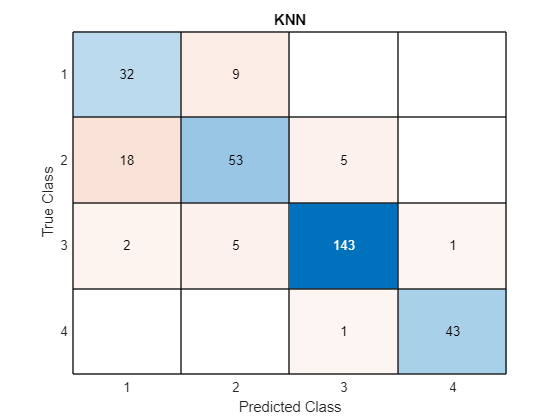

% Fit model
knn = fitcecoc(train,'z',Learners='knn');

% Predict values
knn_y = predict(knn,test);

% Calculate the Accuracy
C = confusionmat(knn_y,test.z);
confusionchart(C);
title('KNN');

accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.87


### **Decision Tree**

Here are conceptual details for [decision trees](https://apmonitor.com/pds/index.php/Main/DecisionTree)

Two ways to train a decision tree in MATLAB are [fitcecoc](https://www.mathworks.com/help/stats/fitcecoc.html) and [`fitrtree`](https://www.mathworks.com/help/stats/decision-trees.html)`. `For more information on decision trees and how to train them see [Decision Trees](https://www.mathworks.com/help/stats/decision-trees.html). 

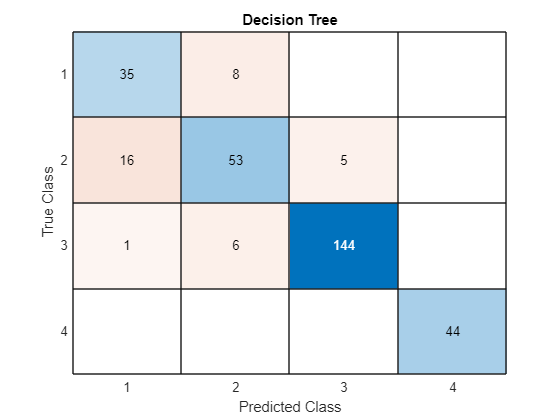

% Fit model
tree = fitcecoc(train,'z',Learners='tree');

% Predict values
tree_y = predict(tree,test);

% Calculate the Accuracy
C = confusionmat(tree_y,test.z);
confusionchart(C);
title('Decision Tree');

accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.88


The [Classification Learner App](https://www.mathworks.com/help/stats/classification-learner-app.html) can be used to interactively train, validate, and tune classification models. The trees can also be trained in parallel which enables the use of large scale training sets. 

### **Discriminant**

Three ways to train a discriminant in MATLAB include [classification discriminant analysis](https://www.mathworks.com/help/stats/classification-discriminant-analysis.html), [discriminat analysis](https://www.mathworks.com/help/stats/discriminant-analysis.html), and [fitcecoc](https://www.mathworks.com/help/stats/fitcecoc.html).

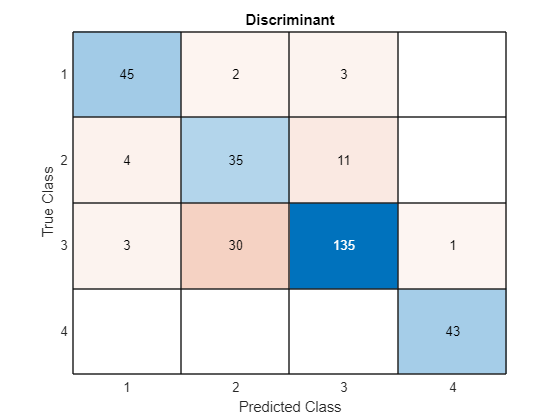

% Fit model
dis = fitcecoc(train,'z',Learners='discriminant');

% Predict values
dis_y = predict(dis,test);

% Calculate the Accuracy
C = confusionmat(dis_y,test.z);
confusionchart(C);
title('Discriminant');

accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.83


### **Naive Bayes**

Two ways to train a discriminant in MATLAB include [single class classification](https://www.mathworks.com/help/stats/naive-bayes-classification.html) and [mulitclass classification](https://www.mathworks.com/help/stats/classificationnaivebayes.html).

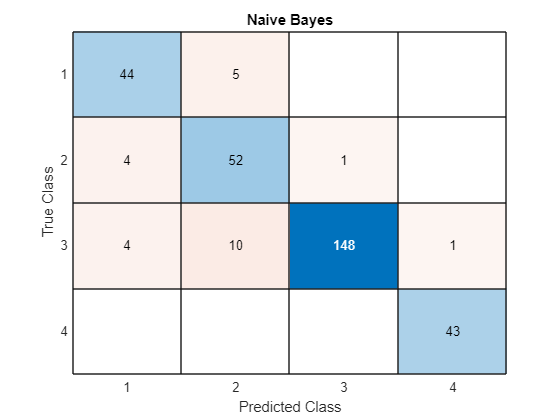

% Fit model
nb = fitcnb(train,'z');

% Predict values
nb_y = predict(nb,test);

% Calculate the Accuracy
C = confusionmat(nb_y,test.z);
confusionchart(C);
title('Naive Bayes');

accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.92


### **Neural Network**

Here are conceptual details for [neural networks](https://www.mathworks.com/discovery/neural-network.html) and [deep learning neural networks](https://apmonitor.com/pds/index.php/Main/DeepLearningNeuralNetwork).

A method to train a neural network in MATLAB is [neural networks classification](https://www.mathworks.com/help/stats/neural-networks-for-classification.html).

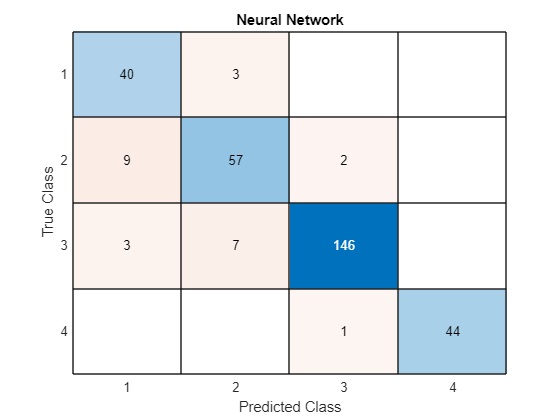

% Scale the data using the zscore function
train_nn = train;
test_nn = test;

% Scale the data for every column except z
for i = 1:width(train) 
    col = train.Properties.VariableNames{i};
    if col ~= "z"
        train_nn.(col) = zscore(train.(col));
        test_nn.(col) = zscore(test.(col));
    end
end

% Fit model
net = fitcnet(train_nn,'z');

% Predict values
net_y = predict(net,test_nn);

% Calculate the Accuracy
C = confusionmat(net_y,test_nn.z);
confusionchart(C);
title('Neural Network');

accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.92


### **Random Forest**

A way to train a neural network in MATLAB is [ensemble of bagged decision trees](https://www.mathworks.com/help/stats/treebagger.html)

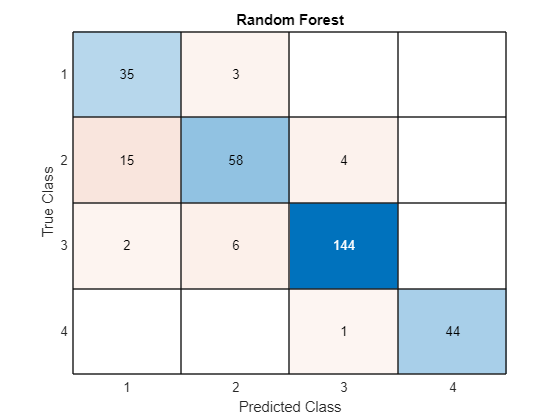

% Fit model
NumTrees = 40;
tbag = TreeBagger(NumTrees,train,'z');

% Predict values
tbag_y = predict(tbag,test);

% Calculate the Accuracy
C = confusionmat(str2double(tbag_y),test.z);
confusionchart(C);
title('Random Forest');

accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.90


The above code from these models are to show how different models classify and possible pros and cons of each.

## Activity

[AdaBoost (Adaptive Boosting) ](https://www.mathworks.com/discovery/adaboost.html)is a machine learning algorithm for classification. It is used as a supervisory layer to other classification algorithms such as neural networks, decisions trees, and support vector machines. It takes weak classifiers as a weighted sum and adaptively refines the output to focus on the harder to classify cases.

Train an AdaBoost classifier with the drawn data. Show a confusion matrix and report the accuracy (%).

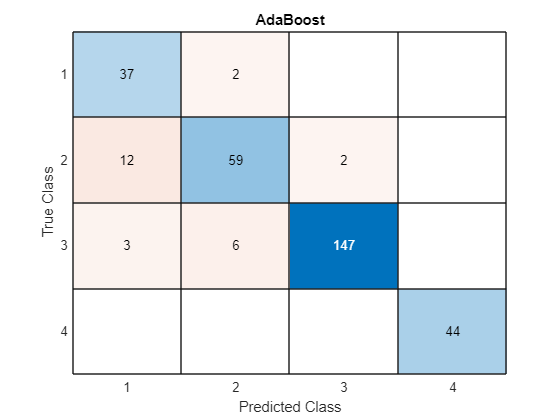

% Fit model
ada = fitcensemble(train,'z','Method','AdaBoostM2');

% Predict values
ada_y = predict(ada,test);

% Calculate the Accuracy
C = confusionmat(ada_y,test.z);
confusionchart(C);
title('AdaBoost');

accuracy = sum(diag(C))/sum(C(:));
fprintf('Accuracy: %.2f\n',accuracy)

Accuracy: 0.92
